# Problem 1

(a) Neither accurate nor precise: 2.3456789101112... this number gives us no indication of what $\sqrt{2}$ is.

(b) Accurate but not precise: 1.50512265... each entry in this number is 1 above or below the true entries in $\sqrt{2}$. Thus, the average difference between the values will give us $\sqrt{2}$.

(c) Precise but not accurate: $\sqrt{2} + 1$ = 2.41421356... this number follows the same trend as $\sqrt{2}$ but is shifted up by 1.

(d) Precise and accurate: 1.41421356... this number is equal to the $\sqrt{2}$.

# Problem 2

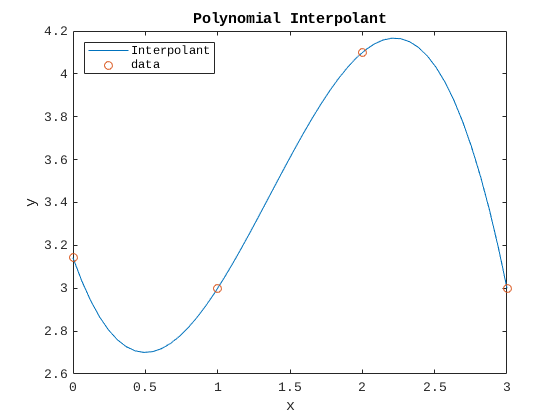

x = (0:3)';
f = [pi; 3; 4.1; 3];

A = x .^ (0:3);

coeff = A\f;

t = linspace(0,3,50)';
ft = (t .^ (0:3)) * coeff;

figure()
plot(t,ft)
hold on
scatter(x,f)
legend('Interpolant','data','Location','northwest')
title('Polynomial Interpolant')
xlabel('x')
ylabel('y')

The plot shows that our polynomial fits the data!

# Problem 3

Suppose $A = \pmatrix{5 & 0 \cr 0 & 2}$. 

We know $||A||_1 \leq ||A||_4 \leq ||A||_\infty$.

But $||A||_1 = 5$ and $||A||_\infty = 5$.

So, we must have $||A||_4 = 5$ to satisfy the inequality. 

To confirm our calculation, consider the plot below:

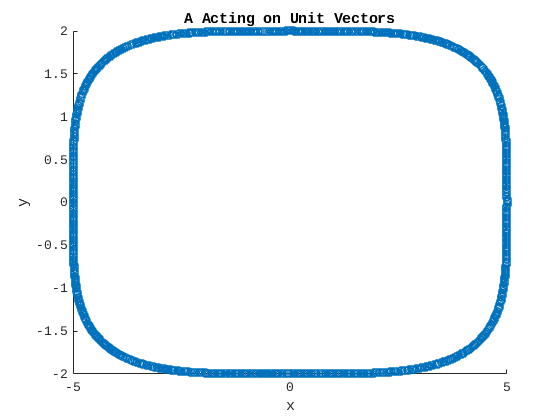

A = [5,0;0,2];
X = rand(2,10000) - 0.5;
for i = 1:10000
    X(:,i) = A*(X(:,i) / norm(X(:,i),4));
end

figure()
scatter(X(1,:),X(2,:))
title('A Acting on Unit Vectors')
xlabel('x')
ylabel('y')

This plot shows the effect of $A$ on unit vectors under the 4-norm. The largest magnitude vector is given the middle vectors on the middle left and middle right of the plot. These middle vectors have magnitude 5 which is what our 5-norm gave us.

#  Problem 4

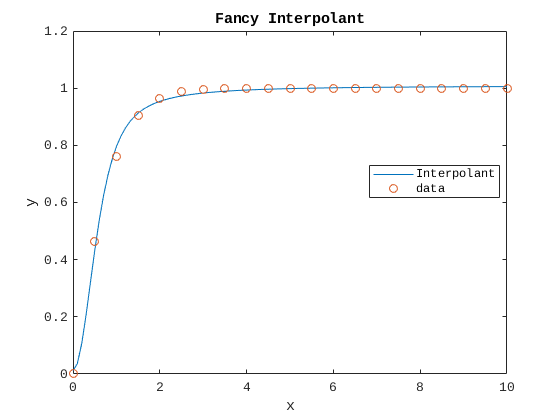

t = linspace(0,10,21)';
y = tanh(t);

f = @(t) t.^2 ./ (1 + t.^2);

A = f(t) .^ (0:3);
coeff = A\y;

x = linspace(0,10,100)';
ft = (f(x) .^ (0:3)) * coeff;

figure()
plot(x,ft)
hold on
scatter(t,y)
title('Fancy Interpolant')
legend('Interpolant','data','Location','best')
xlabel('x')
ylabel('y')

Using the function given in 3.1.4(b), we are able to resolve the data pretty accurately.

# Problem 5

## (a)

A = [0.8, 0.4;
     0.2, 0.6];

## (b)

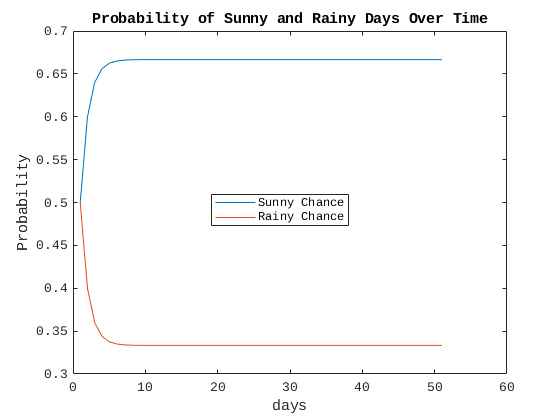

days = 50;
x = zeros(2,days + 1);
x(:,1) = [0.5;0.5];
for i = 2:days + 1
    x(:,i) = A*x(:,i-1);
end

figure()
plot(x')
title('Probability of Sunny and Rainy Days Over Time')
legend('Sunny Chance', 'Rainy Chance','Location',"none")
xlabel('days')
ylabel('Probability')

x(:,end)

ans =    0.666666666666668
   0.333333333333334


The plot shows that we will have predominently sunny days in the future. We should expect $\frac{2}{3}$ of the days will be sunny and $\frac{1}{3}$ of the days will be rainy. In other words, there will be 2 sunny days for every 1 rainy day.

## (c)

[eigVecs, eigVals] = eig(A);
eigVals = diag(eigVals,0)

eigVals =    1.000000000000000
   0.400000000000000


eigVecs

eigVecs =    0.894427190999916  -0.707106781186547
   0.447213595499958   0.707106781186547


From the eigenvectors and values, we can see that the first eigenvector is the dominant state (i.e. the first eigenvalue is the largest while the other eigenvalue is less that zero in absolute value). Thus, the limiting probabilities will be given by the first eigenvector. The entries in the first eigenvector have a ratio of 2 to 1. So, the eigenvector tells us that we should expect 2 sunny days for every 1 rainy day just like our simulation above predicted.

# Problem 6

A = [3,0,0; ...
     0,2,0; ...
     0,0,1];
 
% Compute SVD of A
[U,S,V] = svd(A);

% Compute rank-1 approximation to A from SVD
A1 = U(:,1) * S(1,1) * V(:,1)'

A1 =      3     0     0
     0     0     0
     0     0     0


Thus, the best rank-1 approximation to $A$ is given by $A1 = \pmatrix{3 & 0 & 0 \cr 0 & 0 & 0 \cr 0 & 0 & 0}$.

This approximation seems reasonible because is just a diagonal matrix with largest entry 3. Thus, that largest entry has the most influence over the matrix.